# Homework 5

A = readmatrix("HW4_A.xlsx");
B = [1;0;2;0];
C = [0 1 0 3];
D = 0;
n = size(A,1);   % 4 states

AA = [A B; C 0] ;
bb = [0; 0; 0; 0; 1] ;

K  = [14.594417419680658, 0.999096975937301, -1.297208709840328, 9.145289774526315];
Nu = 2.333388366077816;
Nx = [-0.224863793957405; -0.195311210170051; 0.629464531396181; 0.398437070056684];

Nbar = Nu + K * Nx ;
display(Nbar)

Nbar = 1.6838

## Part(a) Estimator design


$$\dot{e} =\hat{A} e=\left(A-\textrm{LC}\right)e$$


est_poles = [-12, -14, -18, -20];
% Check observability
Ob = obsv(A, C);
fprintf('Observability matrix rank: %d (should be %d)\n', rank(Ob), n);

Observability matrix rank: 4 (should be 4)


% Compute estimator gain L via pole placement  (place A-LC poles)

L = acker(A', C', est_poles)';
 
fprintf('Estimator gain matrix L =\n');

Estimator gain matrix L =


disp(L);

   -0.2533
    7.1309
   12.1527
    9.6230



## Part(b) Autonomous Estimator


$$\begin{array}{l}
u=-K\hat{x} +\bar{N} r\\
\dot{x} =\textrm{Ax}+\textrm{Bu}=\textrm{Ax}-\textrm{BK}\hat{x} +B\bar{N} r\\
y=\textrm{Cx}\\
\dot{\;\hat{x} } =\left(A-\textrm{BK}-\textrm{LC}\right)\hat{x} +\textrm{Ly}+\textrm{Mr}=\left(A-\textrm{BK}-\textrm{LC}\right)\hat{x} +\textrm{Cx}+B\bar{N} r\\
\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{\hat{x} } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
A & -\textrm{BK}\\
C & A-\textrm{BK}-\textrm{LC}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
\hat{x} 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
B\bar{N} \\
B\bar{N} 
\end{array}\right\rbrack r\\
y=\textrm{Cx}+0\cdot \hat{x} 
\end{array}$$


where $M=B\bar{N} \;\left(\textrm{eq}\ldotp 7\ldotp 187\right)$ from Franklin p562 

Acl_b = [A,       -B*K;
         L*C,   A-L*C-B*K];

Bcl_b = [B*Nbar;  
         B*Nbar];  

Ccl_b = [C, zeros(1,n)];
Dcl_b = 0;
ss_sys = ss(Acl_b, Bcl_b, Ccl_b, Dcl_b)


ss_sys =
 
  A = 
            x1       x2       x3       x4       x5       x6       x7       x8
   x1   -8.896   -3.396   -8.028   0.1415   -14.59  -0.9991    1.297   -9.145
   x2    14.62     -8.5    1.875    1.125        0        0        0        0
   x3    13.34    10.09   -10.46    17.29   -29.19   -1.998    2.594   -18.29
   x4    12.76    2.509    5.429  -0.1462        0        0        0        0
   x5        0  -0.2533        0    -0.76   -23.49   -4.142   -6.731   -8.244
   x6        0    7.131        0    21.39    14.62   -15.63    1.875   -20.27
   x7        0    12.15        0    36.46   -15.84   -4.057   -7.863   -37.46
   x8        0    9.623        0    28.87    12.76   -7.114    5.429   -29.02
 
  B = 
          u1
   x1  1.684
   x2      0
   x3  3.368
   x4      0
   x5  1.684
   x6      0
   x7  3.368
   x8      0
 
  C = 
       x1  x2  x3  x4  x5  x6  x7  x8
   y1   0   1   0   3   0   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
<a

 
tt = linspace(0,5.0,400);
yy = step(ss_sys,tt);


Simulation with simulink

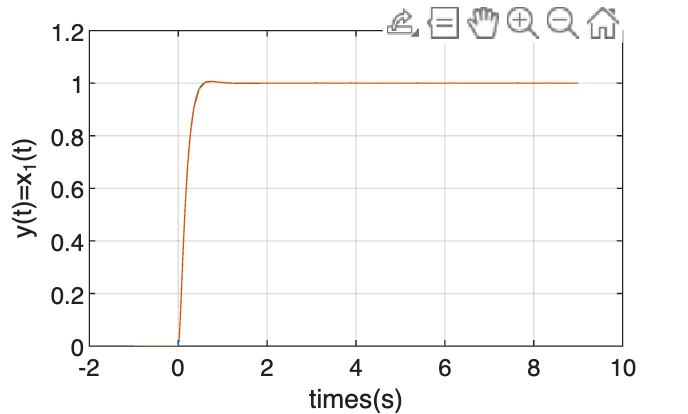

simout = sim(homework5_sim)
figure(1)
plot(tt,yy)
hold on 
t1 = simout.ScopeData.time;
y1 = simout.ScopeData.signals.values;
plot(t1-1,y1)
hold off
grid on
xlabel('times(s)')
ylabel('y(t)=x_1(t)')

## Part(c)


$$\left\lbrack \begin{array}{c}
\dot{x_I } \\
\dot{x} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & C\\
0 & A
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_I \\
x
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
B
\end{array}\right\rbrack u-\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack r+\left\lbrack \begin{array}{c}
0\\
B_1 
\end{array}\right\rbrack w$$



$$u=-\left\lbrack K_1 \;\;K_0 \right\rbrack \left\lbrack \begin{array}{c}
x_I \\
x
\end{array}\right\rbrack$$


where the integrator is $\dot{X_I } =\textrm{Cx}-r\left(=e\right)$

Here in the question, **WE DONT HAVE disturbance w**

% Augmented system with integrator: xi_dot = y - r = Cx - r
A_ic = [0,          C;
        zeros(n,1), A];
B_ic = [0; B];

% Desired poles: HW4 poles + new pole at s = -10
desired_poles_c = [-5+4i, -5-4i, -8, -22, -10];

% Check controllability
Q = ctrb(A_ic, B_ic);
Q

Q = 1.0e+05 *

         0         0    0.0009   -0.0146    0.1829
    0.0000   -0.0002    0.0022   -0.0304    0.9053
         0    0.0002   -0.0051    0.0788   -1.2843
    0.0000   -0.0001    0.0034   -0.1118    2.1592
         0    0.0002   -0.0032    0.0347   -0.8020


fprintf('Augmented controllability rank: %d (should be %d)\n', rank(Q), n+1);

Augmented controllability rank: 5 (should be 5)


rankQ = rank(Q);

% Pole placement
K_ic = place(A_ic, B_ic, desired_poles_c);
fprintf('IMC gain Kc = [K_x | K_i] =\n'); disp(K_ic);

IMC gain Kc = [K_x | K_i] =
   16.8377   20.2846    4.7154    0.8577   18.0374




eig(A_ic - B_ic * K_ic);



$$\left\lbrack \begin{array}{c}
\dot{x_I } \\
\dot{x} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & C\\
0 & A
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_I \\
x
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
B
\end{array}\right\rbrack u-\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack r$$


plug in $u=-\left\lbrack K_1 \;\;K_0 \right\rbrack \left\lbrack \begin{array}{c}
x_I \\
x
\end{array}\right\rbrack$


$$\dot{z} =A_{\textrm{ic}} z-B_{\textrm{ic}} k\cdot z-B_r r$$



$$\dot{z} =\underset{A_{\textrm{cl}} }{\underbrace{\left(A_{\textrm{ic}} -B_{\textrm{ic}} k\right)} z} +\underset{B_{\textrm{cl}} }{\underbrace{\left\lbrack \begin{array}{c}
-1\\
0
\end{array}\right\rbrack } r}$$


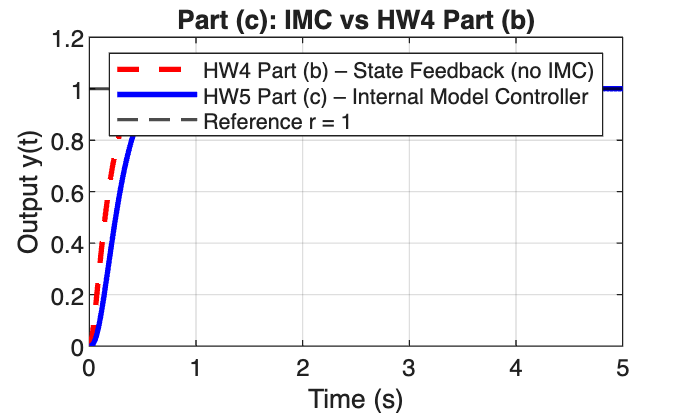

Acl_c = A_ic - B_ic * K_ic;
Bcl_c = [-1; zeros(n,1)];    % input enters through integrator
Ccl_c = [0, C];
Dcl_c = 0;
ss_c = ss(Acl_c, Bcl_c, Ccl_c, Dcl_c);
[y_c, t_c, x_c] = lsim(ss_c, ones(size(t)), t);

% ── Figure 1 comarasion with HW4 Part(b) ──────────────────────────────
% HW4 Part(b): full state feedback, u = -Kx + Nu*r
sys_hw4b = ss(A - B*K, B*Nbar, C, 0);
[y_hw4b, ~] = lsim(sys_hw4b, ones(size(t)), tt);

figure;
plot(t,    y_hw4b, 'r--', 'LineWidth', 2); hold on;
plot(t_c,  y_c,   'b',   'LineWidth', 2);
yline(1, 'k--', 'LineWidth', 1.2);
xlabel('Time (s)'); ylabel('Output y(t)');
title('Part (c): IMC vs HW4 Part (b)');
legend('HW4 Part (b) – State Feedback (no IMC)', ...
       'HW5 Part (c) – Internal Model Controller', ...
       'Reference r = 1');
grid on;

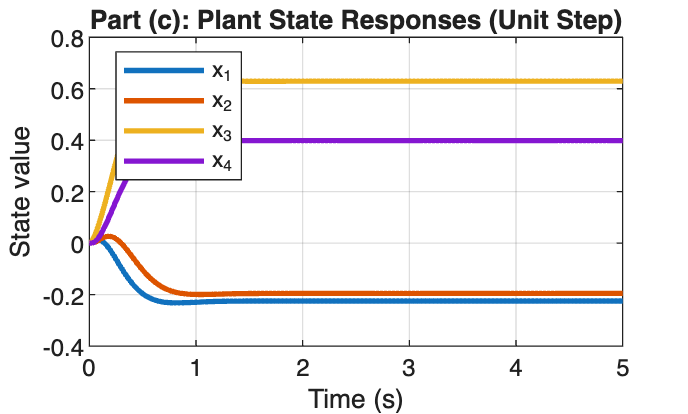


% ── Figure 2：response of all plant statas ──────────────────────────────────
% x_c 的列: [x1, x2, x3, x4, xi],
figure;
colors = lines(4);
for k = 1:n
    plot(t_c, x_c(:, k+1), 'Color', colors(k,:), 'LineWidth', 2); hold on;
end
xlabel('Time (s)'); ylabel('State value');
title('Part (c): Plant State Responses (Unit Step)');
legend('x_1','x_2','x_3','x_4', 'Location','best');
grid on;